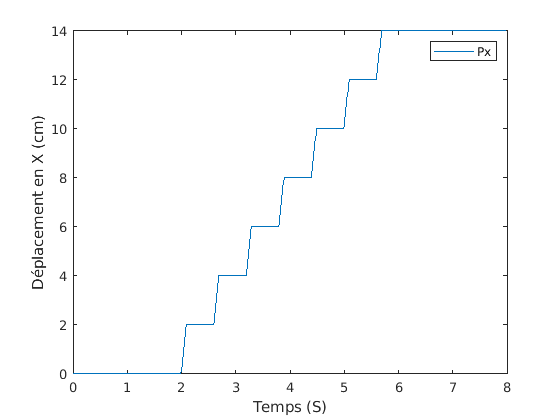

global zmprefx
global zmprefy
global temps_un_pas 
global Ts
  
time_end = 8;
steps = floor(time_end / Ts);
time = 0;
N=7;
dX=2;

single_support = 0.5;
double_support = 0.2 * single_support;
temps_un_pas = single_support + double_support

zmprefx=[];
zmprefy=[];
[pxref, pyref] = create_step_pattern(dX, 0.05, N, single_support, Ts, time_end, double_support, 2);
tplot = [];
for step = 1:steps
    tplot = [tplot time];
    zmprefx = [zmprefx,  pxref(step)];
    zmprefy = [zmprefy,  pyref(step)];
    time = time + Ts;
end

plot(tplot, zmprefx);

y_ticks = 0:dX:N*dX;

% Set the x-axis ticks
yticks(y_ticks);
xlabel('Temps (S)')
ylabel('Déplacement en X (cm)')
legend('Px');

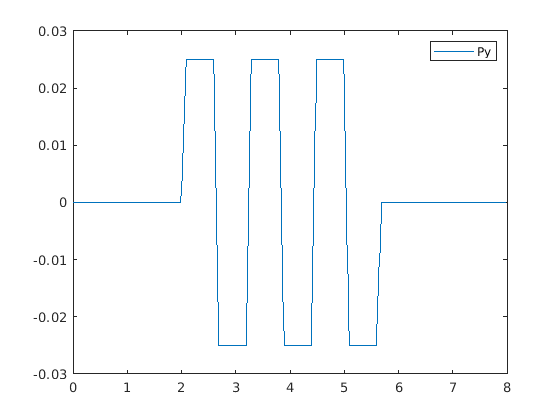



plot(tplot, zmprefy);
legend('Py');

Zc = 0.08;  % Height of center of mass
Xz=1;
g=9.81;
trajectoire_centre_de_masse_x = find_com_trajectory(zmprefx, Zc, Ts)

trajectoire_centre_de_masse_x =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


trajectoire_centre_de_masse_y = find_com_trajectory(zmprefy, Zc, Ts)

trajectoire_centre_de_masse_y =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


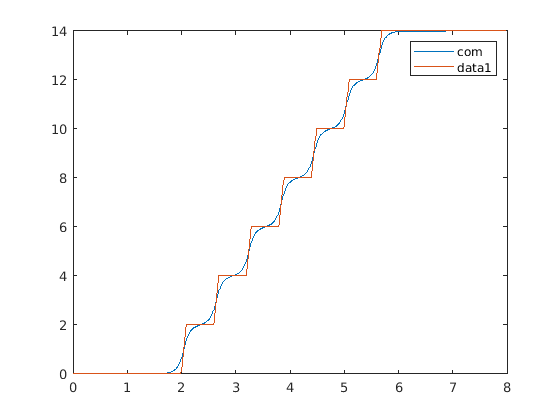

plot(tplot, trajectoire_centre_de_masse_x);
legend('com');
hold on 
plot(tplot, zmprefx)
hold off

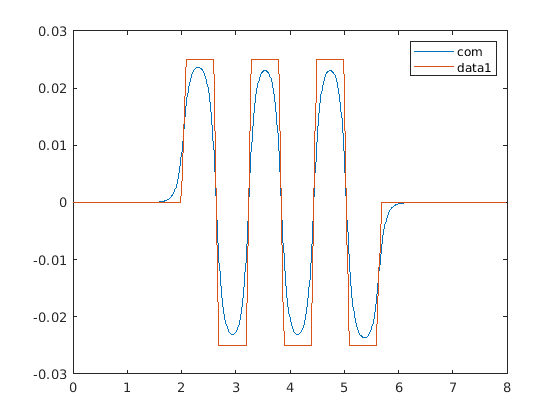

plot(tplot, trajectoire_centre_de_masse_y);
legend('com');
hold on 
plot(tplot, zmprefy)


pelvis_x = trajectoire_centre_de_masse_x + 0.015;

### **function de create_step_pattern**

function [pxref, pyref] = create_step_pattern(dX, dY, N, TempsSingleSupport, Ts, Tend, TDoubleSupport, TIdleTime)
    % Inputs:
    %     dX (float): Step length in X direction
    %     dY (float): Step distance in sideways direction (Y)
    %     N (int): Amount of steps to take
    %     Tstep (float): Duration of the step in seconds
    %     Ts (float): Sampling time in seconds
    %     Tend (float): Simulation end time in seconds
    % 
    % Outputs:
    %     Tuple of
    %         prefx: Array of step positions in X direction
    %         prefy: Array of step positions in Y direction
    pxref = [];
    pyref = [];

    total_samples = floor(Tend / Ts);
    samples_per_single_support = floor(TempsSingleSupport / Ts);
    samples_per_double_support = floor(TDoubleSupport / Ts);
    sample_for_idle_time = floor(TIdleTime / Ts);       % Idle one step period
    dx_step_per_sample = dX / samples_per_double_support;
    dy_step_per_sample_full = dY / samples_per_double_support;
    dy_step_per_sample_half = (dY / 2) / samples_per_double_support;
    sample_count = 0;
    
    for i = 0: sample_for_idle_time - 1
        pxref = [pxref 0];
        pyref = [pyref 0];
        
        sample_count = sample_count + 1;
    end
    
    for i = 1 : N
        if size(pxref) > total_samples
            break
        end
        last_sample_for_double_support = sample_count + samples_per_double_support;
        while sample_count < last_sample_for_double_support
            %%% Calculer y
            if i == 1
                next_y = pyref(end) + dy_step_per_sample_half;
                
            elseif i == N
                if rem(i, 2) == 0
                    next_y = pyref(end) - dy_step_per_sample_half;
                else
                    next_y = pyref(end) + dy_step_per_sample_half;
                end
            elseif rem(i, 2) == 0
                next_y = pyref(end) - dy_step_per_sample_full;    
            else
                next_y = pyref(end) + dy_step_per_sample_full; 
            end
            pyref = [pyref next_y];
            %%% Calculer x
            next_x = (pxref(end) +dx_step_per_sample);
            pxref = [pxref next_x];
            sample_count = sample_count + 1;
        end
        last_sample_for_single_support = sample_count + samples_per_single_support;
        while sample_count < last_sample_for_single_support
            next_x = pxref(end);
            pxref = [pxref next_x];
            next_y = pyref(end);
            pyref = [pyref next_y];
            sample_count = sample_count + 1;
        end
    end
    
    while sample_count < total_samples 
        next_x = pxref(end);
        next_y = pyref(end);
        pxref = [pxref next_x];
        pyref = [pyref next_y];
        sample_count = sample_count + 1;
    end
end



function [trajectoire_centre_masse] = find_com_trajectory(path, Zc, Ts)
    g = 9.81;
    trajectoire_centre_masse = [];
    A = zeros(length(path), length(path));
    a = -Zc / (g*Ts^2);
    b = (2 * Zc / (g * Ts^2)) + 1;
    c = a;
    A(1,1) = a + b;
    A(1,2) = c;
    A(1,3) = 0;
    for current_point = 2 : length(path) - 1
        A(current_point, current_point - 1) = a;
        A(current_point, current_point) = b;
        A(current_point, current_point + 1) =  c;
    end
    A(length(path), length(path) -1) = a;
    A(length(path), length(path)) = b + c;
    trajectoire_centre_masse = pinv(A) * path';
end
